# Exercise 3

## Mesh

### Definitions

D1 = 2; % m
D2 = 4; % m
cpm = 5;    % cells per m

U1_mean = 1; % m/s

Re1 = 20000;

### kinematic viscosity

for the given Reynolds number, from $Re=\frac{U\,D}{\nu}$

nu = U1_mean*D1/Re1

nu = 1.0000e-04

### Entrance lengths

Length, after which the flow should be fully developed.

$L_h = 1.359\,Re^{\frac{1}{4}$ according to [1] [p.405]

U2_mean = U1_mean*(D1^2*pi/4)/(D2^2*pi/4)

U2_mean = 0.2500

Re2 = U2_mean*D2/nu

Re2 = 10000


L_h1 = 1.359*Re1^(1/4)*D1  % entrance length 1

L_h1 = 32.3226

L_h2 = 1.359*Re2^(1/4)*D2  % entrance length 2

L_h2 = 54.3600


L_12 = ceil(L_h1)+1     % length pipe segment 1-2 and 3-4

L_12 = 34

L_23 = ceil(L_h2)+1     % length pipe segment 2-3

L_23 = 56


nCells_12 = L_12*cpm

nCells_12 = 170

nCells_23 = L_23*cpm

nCells_23 = 280


mx1 = 0

mx1 = 0

mx2 = L_12

mx2 = 34

mx3 = L_12+L_23

mx3 = 90

mx4 = 2*L_12+L_23

mx4 = 124

## Turbulence

I = 0.05;
Cmu = 0.09;
lm = 0.07*D1;     % 0.1*step height
k = 3/2*(U1_mean*I)^2

k = 0.0038

epsilon = Cmu^(0.75)*k^(1.5)/lm

epsilon = 2.6953e-04

omega = epsilon/(Cmu*k)

omega = 0.7986

## Analytic solution

### Definitions

rho = 1000;

### Minor Losses

Formula for minor losses from [1] [p.307] and chart.

k_exp = 1.05 * (1 - (D1^2/D2^2))^2

k_exp = 0.5906

dp_exp = k_exp*rho*U1_mean^2/2

dp_exp = 295.3125


A_frac = D1^2/D2^2

A_frac = 0.2500

k_contr = 0.4

k_contr = 0.4000

dp_contr = k_contr*rho*U1_mean^2/2

dp_contr = 200

### Major Losses

Calced with Prandtl's implicit equation $\frac{1}{\sqrt{f}}=2\,\log{(Re\,\sqrt{f})}-0.8$

f12 = 0.031;    % initil from moody
for i = 1:20
    invf12 = 2*log10(Re1*sqrt(f12)) - 0.8;
    f12 = (1/invf12)^2;
end
f12     % small pipe

f12 = 0.0259


f23 = 0.04;     % same
for i = 1:20
    invf23 = 2*log10(Re2*sqrt(f23)) - 0.8;
    f23 = (1/invf23)^2;
end
f23     % big pipe

f23 = 0.0309

### Bernoulli 3-4

alpha1 = 1.05;
alpha2 = 1.05;
p3 = 0 + f12 * (L_12/D1) * rho * U1_mean^2 / 2

p3 = 220.0467

p3n = p3 + (alpha1*rho*U1_mean^2/2 - alpha2*rho*U2_mean^2/2) + ...
    dp_contr

p3n = 912.2342

### Bernoulli 2-3

alpha1 = 1.05;
alpha2 = 1.05;
p2 = p3n + f23 * (L_23/D2) * rho * U2_mean^2 / 2

p2 = 925.7482

p2n = p2 + (alpha2*rho*U2_mean^2/2 - alpha1*rho*U1_mean^2/2) + dp_exp

p2n = 728.8732

### Bernoulli 1-2

alpha1 = 1.05;
alpha2 = 1.05;
p1 = p2n + f12 * (L_12/D1) * rho * U1_mean^2 / 2;

### Plot

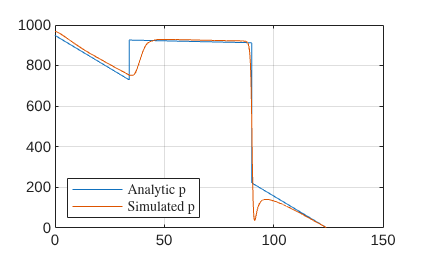

x1 = 0;
x2 = L_12;
x3 = x2 + L_23;
x4 = x3 + L_12;

x = [x1, x2, x2, x3, x3, x4];
p = [p1, p2n, p2, p3n, p3, 0];

data = readmatrix("p_rotax_long.csv");
xd = data(:,9);
pd = data(:,6)*rho;

plot(x, p)
hold on, grid on
plot(xd, pd)
legend('Analytic p', 'Simulated p', ...
    'Interpreter', 'latex', 'Location','southwest')
hold off

## Sources

[1] Fluid Mechanics Fundamentals and Applications 3rd Edition, Çengel, Yunus A, Cimbala